Anant Mital 

Student # 272484

## Problem 2

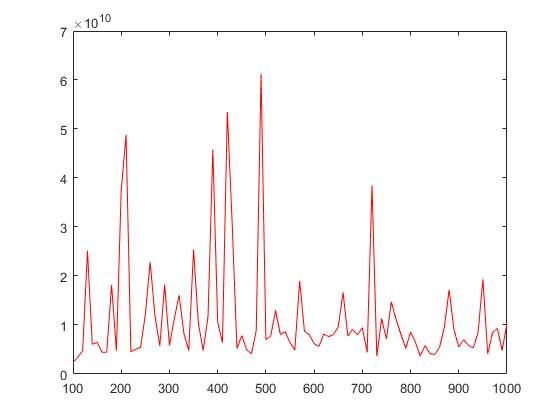

x = 100:10:1000;
y = zeros(1,length(x));
index = 1;
for n = x    
    A = randi([-10,10],n,n);
    Xe = ones(n,1);
    b = A*Xe;
    X = A\b;
    u = 5.9605*(10^-8);
    L = norm((X-Xe), inf)/norm(X,inf);
    R = u*cond(A,inf);
    y(index) = R/L;
    index = index + 1;
end

figure;
plot(x,y,'r');